netlistTable = readtable('Netlist excel\4_Stubs_Netlist.xlsx')           

netlistTable = 11×7 table
     Nombre     NodoInicial    NodoFinal    componente     valor     longitudElectrica    Frecuencia
    ________    ___________    _________    __________    _______    _________________    __________

    {'C1'  }      {'N1'}        {'N3'}       {'C'  }      1.2e-11            0                  0   
    {'R1'  }      {'N3'}        {'N0'}       {'R'  }           75            0                  0   
    {'C2'  }      {'N3'}        {'N4'}       {'C'  }      1.2e-11            0                  0   
    {'SSC1'}      {'N4'}        {'N0'}       {'SSC'}        62.83           45              1e+09   
    {'C3'  }      {'N4'}        {'N5'}       {'C'  }      1.2e-11            0                  0   
    {'R2'  }      {'N5'}    

Stubs_Pruebas=sparameters('Touchstone files\ElementosDistribuidos\4_Stubs_PruebasProyectoSParams.s2p')

Stubs_Pruebas =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij



netlistCell= table2cell(netlistTable)

netlistCell = 11×7 cell array
    {'C1'  }    {'N1'}    {'N3'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'R1'  }    {'N3'}    {'N0'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'C2'  }    {'N3'}    {'N4'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'SSC1'}    {'N4'}    {'N0'}    {'SSC'}    {[   62.8300]}    {[45]}    {[1.0000e+09]}
    {'C3'  }    {'N4'}    {'N5'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'R2'  }    {'N5'}    {'N0'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'SOC1'}    {'N5'}    {'N6'}    {'SOC'}    {[   13.2600]}    {[45]}    {[1.0000e+09]}
    {'L2'  }    {'N6'}    {'N0'}    {'L'  }    {[1.0000e-08]}    {[ 0]}    {[         0]}
    {'C4'  }    {'N6'}    {'N7'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'R3'  }    {'N7'}    {'N0'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'SOC2'}    {'N7'}    {'N2'}    {'SOC'}    {[   13.2600]}    {[45]

Frec_inicial=0.1E9;
Frec_final=2E9;
Muestreo=1000;
Z0=50;


SMatlab=SParametersFromNetlist(netlistCell,Frec_inicial,Frec_final,Muestreo,Z0)

nodoInicial = 1

nodoFinal = 3

type = 'C'

value = 1.2000e-11

Bl = 0

Bl = 0

opFreq = 0

nodoInicial = 3

nodoFinal = 0

type = 'R'

value = 75

Bl = 0

Bl = 0

opFreq = 0

nodoInicial = 3

nodoFinal = 4

type = 'C'

value = 1.2000e-11

Bl = 0

Bl = 0

opFreq = 0

nodoInicial = 4

nodoFinal = 0

type = 'SSC'

value = 62.8300

Bl = 45

Bl = 0.7854

opFreq = 1.0000e+09

Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubCorto'
                    Z0: 62.8300
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Short'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}
           ParentNodes: [4 0 0 0]
            ParentPath: 'unnamed'


nodoInicial = 4

nodoFinal = 5

type = 'C'

value = 1.2000e-11

Bl = 0

Bl = 0

opFreq = 0

nodoInicial = 5

nodoFinal = 0

type = 'R'

value = 75

Bl = 0

Bl = 0

opFreq = 0

nodoInicial = 5

nodoFinal = 6

type = 'SOC'

value = 13.2600

Bl = 45

Bl = 0.7854

opFreq = 1.0000e+09

Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubOpen'
                    Z0: 13.2600
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Open'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}
           ParentNodes: [5 6 0 0]
            ParentPath: 'unnamed'


nodoInicial = 6

nodoFinal = 0

type = 'L'

value = 1.0000e-08

Bl = 0

Bl = 0

opFreq = 0

nodoInicial = 6

nodoFinal = 7

type = 'C'

value = 1.2000e-11

Bl = 0

Bl = 0

opFreq = 0

nodoInicial = 7

nodoFinal = 0

type = 'R'

value = 75

Bl = 0

Bl = 0

opFreq = 0

nodoInicial = 7

nodoFinal = 2

type = 'SOC'

value = 13.2600

Bl = 45

Bl = 0.7854

opFreq = 1.0000e+09

Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubOpen_1'
                    Z0: 13.2600
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Open'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}
           ParentNodes: [7 2 0 0]
            ParentPath: 'unnamed'


SMatlab =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [1000×1 double]
     Parameters: [2×2×1000 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


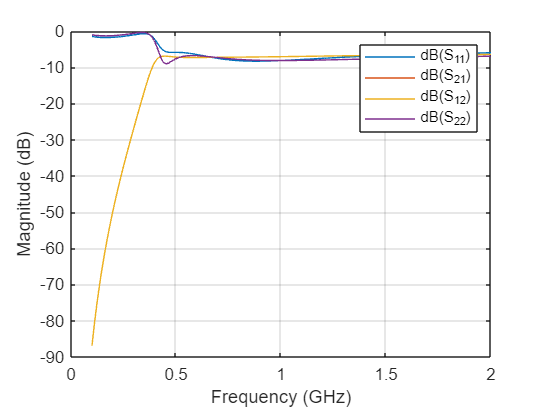

rfplot(SMatlab)

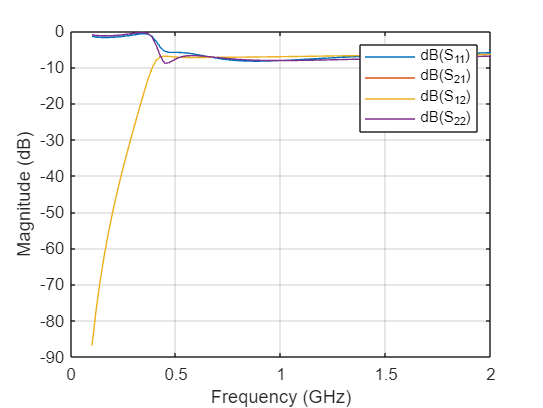

rfplot(Stubs_Pruebas)